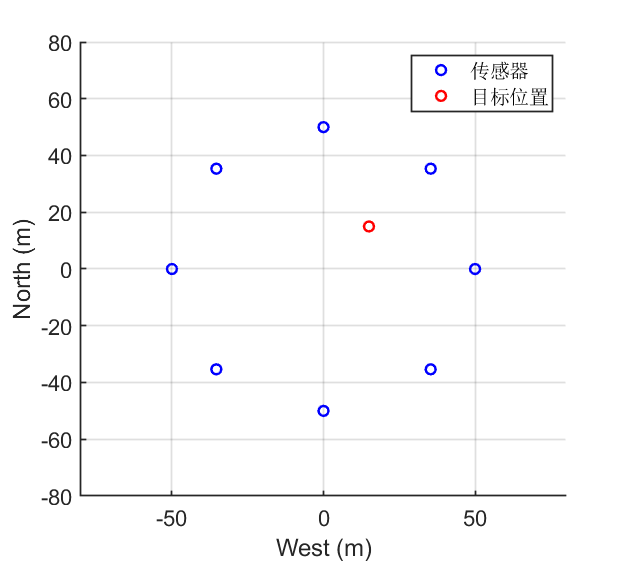

%% 模型设置
N=8; % 传感器个数
x_target=[15;15]; % 目标位置

% 传感器位置
rad=50;
for i=1:N 
    s(1,i)=rad*cos(2*pi*(i-1)/N);
    s(2,i)=rad*sin(2*pi*(i-1)/N);
    S(:,:,i)=[eye(2) -s(:,i); -s(:,i).' s(:,i).'*s(:,i)];
end

% 成图
scatter(s(1,:),s(2,:),'b','LineWidth',1.5); hold on
scatter(x_target(1),x_target(2),'r','LineWidth',1.5); hold off
set(gca,'LineWidth',1);
axis([-80 80 -80 80]);
% set(gca,'Xtick',2800:100:3200);
% set(gca,'Ytick',0.5:0.1:0.9);
set(gca,'FontSize',13);
xlabel('West (m)','Fontname','LucidaBrightRegular','FontSize',10);
ylabel('North (m)','Fontname','LucidaBrightRegular','FontSize',10);
set(gcf,'Position',[180,180,500,450]);grid on
legend('传感器','目标位置','Location','NorthEast');

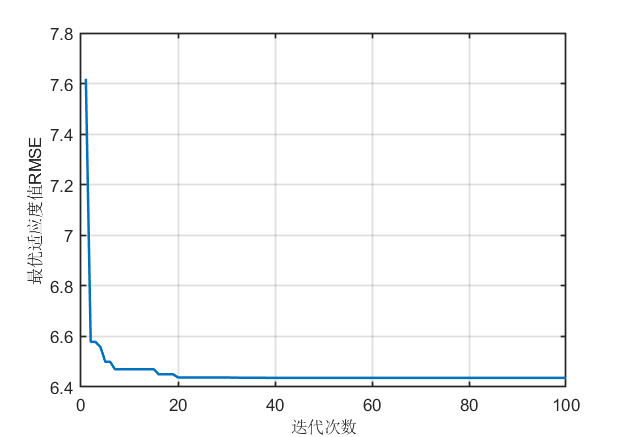


%% 优化过程 (单噪音测试)

tic

% 传感器接收信号RSS
sigma=1; % 噪音
alpha=3; d0=1; L0=40; rad=50; % 传感器参数设置
L=rss_foward(N,alpha,d0,L0,rad,sigma,x_target); % 传感器接收信号
for i=1:N 
    s(1,i)=rad*cos(2*pi*(i-1)/N);
    s(2,i)=rad*sin(2*pi*(i-1)/N);
end

% 粒子群优化参数设置
num_ptc=20; % 粒子数
num_gen=100; % 迭代次数
c1=2; c2=2; % 惯性系数，学习因子

% 存储向量
L_best=zeros(N,1);
L_new=zeros(N,1);
ptcs=zeros(num_ptc,2); % 粒子
vel=zeros(num_ptc,2); % 速度
fit_P=zeros(num_ptc,1);  % 适应度存储向量
Pi=zeros(num_ptc,2); % 全体最优粒子
vel_max=2; % 速度最大值
Pbest=zeros(num_gen,1); % 存储RMSE(收敛过程)

% 随机设置粒子初始位置和速度
for i=1:num_ptc
    for j=1:2
        ptcs(i,j)=50*(rand-0.5); % 初始粒子位置
        vel(i,j)=(0.5-rand)*2*vel_max; % 初始粒子速度
    end
end         

% 计算初始粒子适应度值，设置初始个体最优粒子和全体最优粒子
for i=1:num_ptc

    for j=1:N
        L_best(j)=L0+10*alpha*log10(norm(ptcs(i,:)'-s(:,j))/d0);
    end
    e_best=sum(abs(L_best-L)); % 适应度值
    
    fit_P(i)=e_best;                    
    Pi(i,:)=ptcs(i,:); % 初始个体最优粒子

end

[P_min,P_index]=min(fit_P);
Pg=ptcs(P_index,:);
fit_Pg=P_min; % 初始全体最优粒子

% 更新迭代主程序

for t=1:num_gen
        
      for i=1:num_ptc
            
            for j=1:2
                
                w(t)=(1-(1-0.1)*(t/num_gen))*exp(-t/num_gen); % 权重系数对数降低
%                 w(t)=1;                                      % 权重为常数
                vel(i,j)=w(t)*vel(i,j)+c1*rand*(Pi(i,j)-ptcs(i,j))+c2*rand*(Pg(j)-ptcs(i,j)); % 速度更新
                 
                % 限定速度范围
                if vel(i,j)>vel_max
                   vel(i,j)=vel_max;
                end   
            
                if vel(i,j)<-vel_max
                   vel(i,j)=-vel_max;
                end 
                
                % 更新粒子位置
                ptcs(i,j)=ptcs(i,j)+w(t)*vel(i,j);
        
            end
        
        % 计算更新位置后的粒子适应度值    
        for j=1:N
             L_best(j)=L0+10*alpha*log10(norm(ptcs(i,:)'-s(:,j))/d0);
        end
        e_best_new=sum(abs(L_best-L)); % 新的适应度值
    
            if e_best_new<fit_P(i)
               fit_P(i)=e_best_new;
               Pi(i,:)=ptcs(i,:);
            end
        
            if fit_P(i)<fit_Pg
               Pg=Pi(i,:);
               fit_Pg=fit_P(i);
            end
      end
        
      Pbest(t)=fit_Pg;  % 存储全体最优适应度值（收敛过程）
        
end

%% 仿真结果成图
% 迭代过程
figure
plot(1:num_gen,Pbest,'LineWidth',1.5);
set(gca,'LineWidth',1); 
set(gca,'FontSize',10);
xlabel('迭代次数','Fontname','LucidaBrightRegular','FontSize',10);
ylabel('最优适应度值RMSE','Fontname','LucidaBrightRegular','FontSize',10);
set(gcf,'Position',[180,180,500,350]);grid on

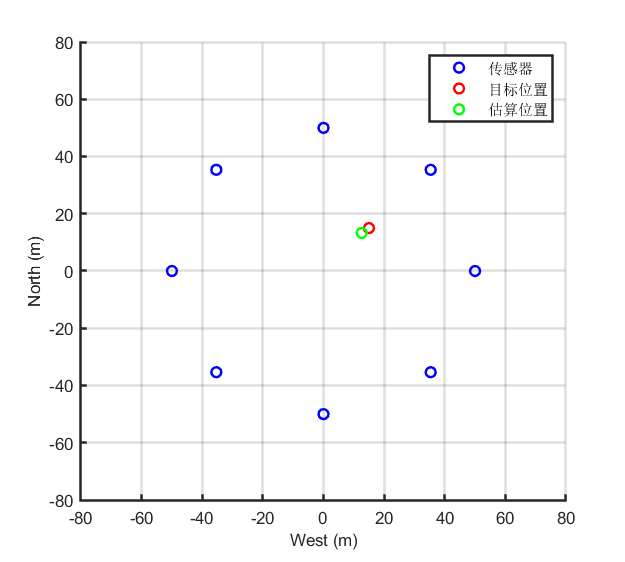


figure
scatter(s(1,:),s(2,:),'b','LineWidth',1.5); hold on
scatter(x_target(1),x_target(2),'r','LineWidth',1.5); hold on
scatter(Pg(1),Pg(2),'g','LineWidth',1.5); hold off
set(gca,'LineWidth',1.5);
axis([-80 80 -80 80]);
set(gca,'FontSize',10);
xlabel('West (m)','Fontname','LucidaBrightRegular','FontSize',10);
ylabel('North (m)','Fontname','LucidaBrightRegular','FontSize',10);
set(gcf,'Position',[180,180,500,450]);grid on
legend('传感器','目标位置','估算位置','Location','NorthEast');


%% 多噪音测试

tic

M1=100; % 测试次数
sigmav=1:1:20; % 测试噪音
rms_ave=zeros(1,length(sigmav));
rms_rss=zeros(M1,length(sigmav));

for i=1:N 
    s(1,i)=rad*cos(2*pi*(i-1)/N);
    s(2,i)=rad*sin(2*pi*(i-1)/N);
end 

% 粒子群优化参数设置
num_ptc=20; % 粒子数
num_gen=100; % 迭代次数
c1=2; c2=2; % 惯性系数，学习因子

for sig=1:length(sigmav)

alpha=3; d0=1; L0=40; rad=50; % 传感器参数设置
L=rss_foward(N,alpha,d0,L0,rad,sigmav(sig),x_target); % 传感器接收信号
   
    for k=1:M1
        
    % 存储向量
    L_best=zeros(N,1);
    L_new=zeros(N,1);
    ptcs=zeros(num_ptc,2); % 粒子
    vel=zeros(num_ptc,2); % 速度
    fit_P=zeros(num_ptc,1);  % 适应度存储向量
    Pi=zeros(num_ptc,2); % 全体最优粒子
    vel_max=2; % 速度最大值
    Pbest=zeros(num_gen,1); % 存储RMSE(收敛过程)

    % 随机设置粒子初始位置和速度
    for i=1:num_ptc
        for j=1:2
            ptcs(i,j)=50*(rand-0.5); % 初始粒子位置
            vel(i,j)=(0.5-rand)*2*vel_max; % 初始粒子速度
        end
    end         

    % 计算初始粒子适应度值，设置初始个体最优粒子和全体最优粒子
    for i=1:num_ptc

        for j=1:N
            L_best(j)=L0+10*alpha*log10(norm(ptcs(i,:)'-s(:,j))/d0);
        end
        e_best=sum(abs(L_best-L)); % 适应度值
    
        fit_P(i)=e_best;                    
        Pi(i,:)=ptcs(i,:); % 初始个体最优粒子

    end

    [P_min,P_index]=min(fit_P);
    Pg=ptcs(P_index,:);
    fit_Pg=P_min; % 初始全体最优粒子

% 更新迭代主程序

    for t=1:num_gen
        
          for i=1:num_ptc
            
            for j=1:2
                
                w(t)=(1-(1-0.1)*(t/num_gen))*exp(-t/num_gen); % 权重系数对数降低
%                 w(t)=1;                                        % 权重为常数
                vel(i,j)=w(t)*vel(i,j)+c1*rand*(Pi(i,j)-ptcs(i,j))+c2*rand*(Pg(j)-ptcs(i,j)); % 速度更新
                 
                % 限定速度范围
                if vel(i,j)>vel_max
                   vel(i,j)=vel_max;
                end   
            
                if vel(i,j)<-vel_max
                   vel(i,j)=-vel_max;
                end 
                
                % 更新粒子位置
                ptcs(i,j)=ptcs(i,j)+w(t)*vel(i,j);
        
            end
        
        % 计算更新位置后的粒子适应度值    
              for j=1:N
                   L_best(j)=L0+10*alpha*log10(norm(ptcs(i,:)'-s(:,j))/d0);
              end
              e_best_new=sum(abs(L_best-L)); % 新的适应度值
    
              if e_best_new<fit_P(i)
                 fit_P(i)=e_best_new;
                 Pi(i,:)=ptcs(i,:);
              end
        
              if  fit_P(i)<fit_Pg
                  Pg=Pi(i,:);
                  fit_Pg=fit_P(i);
              end
          end
        
       Pbest(t)=fit_Pg;  % 存储全体最优适应度值（收敛过程）
      
       
    end
    
       rms_rss(k,sig)=fit_Pg; % 每次测试的最佳目标函数值rms
    
    end
    
     rms_ave(sig)=sqrt(sum(rms_rss(:,sig))/M1); % M1次测试最佳目标函数值rms的平均值(记录不同噪音下的rms)
%        rms_ave(sig)=min(rms_rss(:,sig));
       disp(sig)     
    
end

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20




toc

时间已过 242.823269 秒。


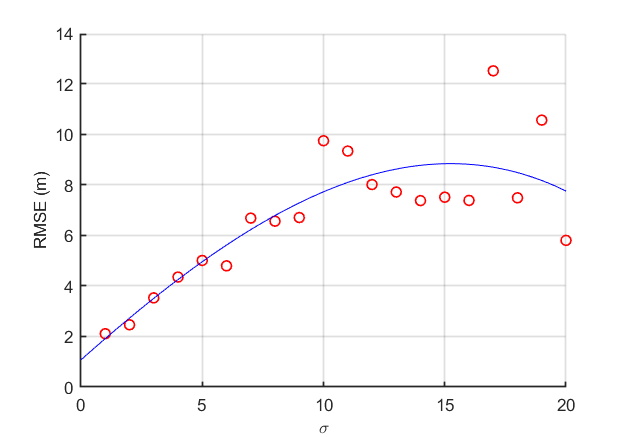


%% 多噪音测试结果成图(不同噪音下的最佳rms)
figure
rms_aver=rms_ave;
% plot(sigmav,rms_aver);hold on ;
box off
scatter(sigmav,rms_aver,'r','LineWidth',1.0); hold on;grid on
a=polyfit(sigmav,rms_aver,3);
x0=0:0.1:20;
y0=polyval(a,x0);
plot(x0,y0,'-b');hold off
set(gca,'LineWidth',1);
% axis([1 6 0 18]);
% set(gca,'Xtick',1:0.5:6);
% set(gca,'Ytick',0:2:18);
% set(gca,'xdir','reverse'); 
set(gca,'FontSize',10);
xlabel('\sigma','Fontname','LucidaBrightRegular','FontSize',10);
ylabel('RMSE (m)','Fontname','LucidaBrightRegular','FontSize',10);
set(gcf,'Position',[180,180,500,350]);grid on